clear
close
clc

load chestVolume.mat
whos

  Name        Size                     Bytes  Class    Attributes

  V         512x512x318            166723584  int16              



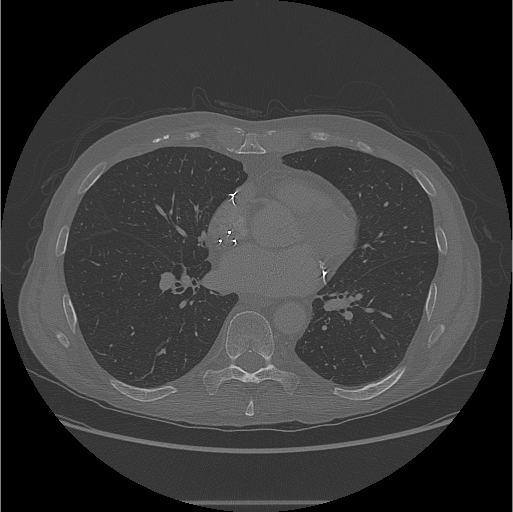

V=im2single(V);

XY=squeeze(V(:,:,160));
imshow(XY,[],'Border','tight')

level = thresh_tool(XY, 'gray');

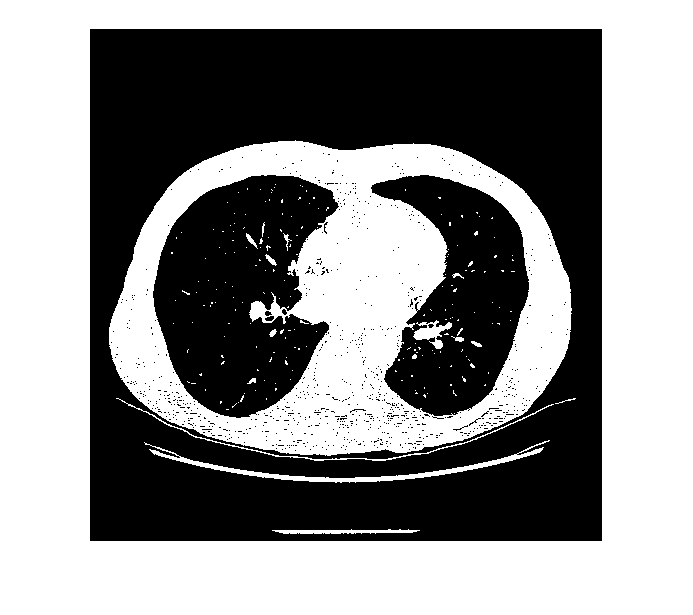

BW=XY>level;
imshow(BW,[])

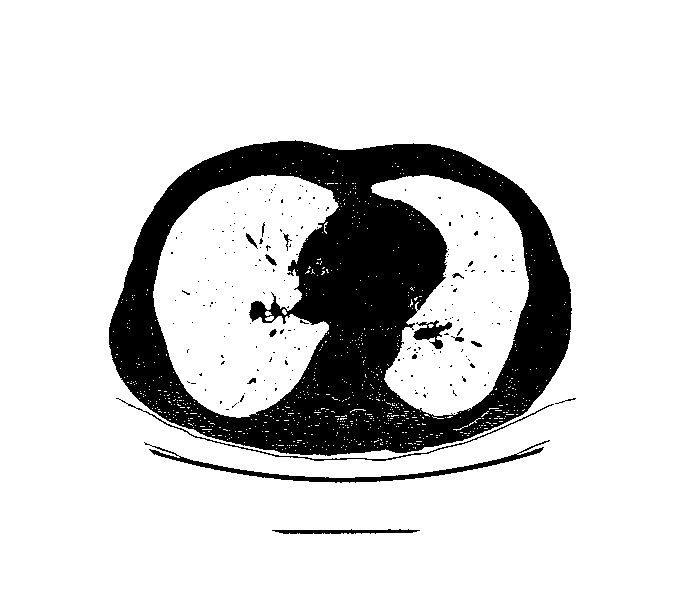

inverse=imcomplement(BW);
imshow(inverse,[])

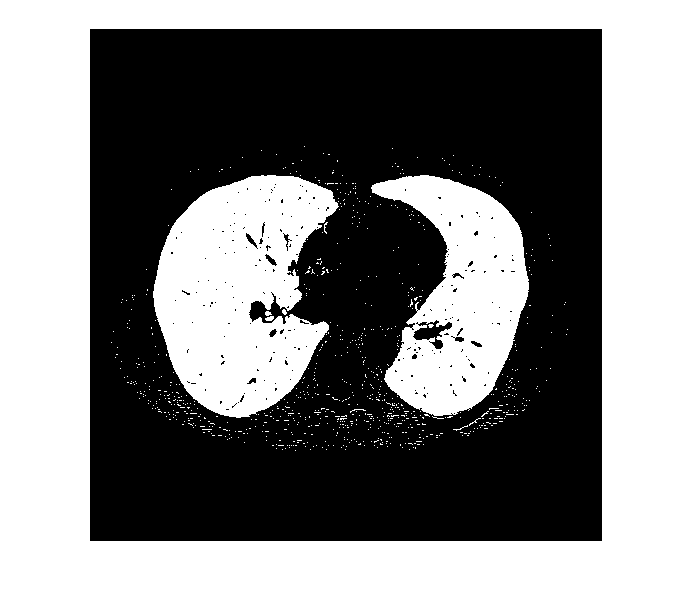

borderclr=imclearborder(inverse);
imshow(borderclr)

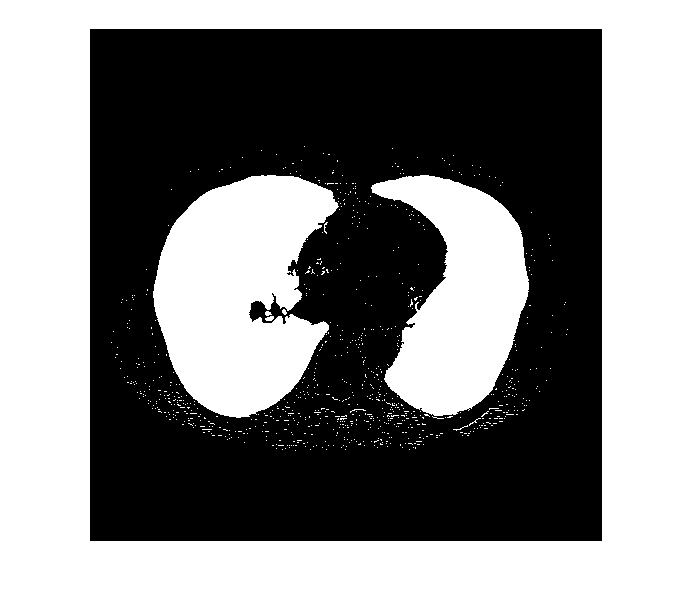

filled=imfill(borderclr,'holes');
imshow(filled)

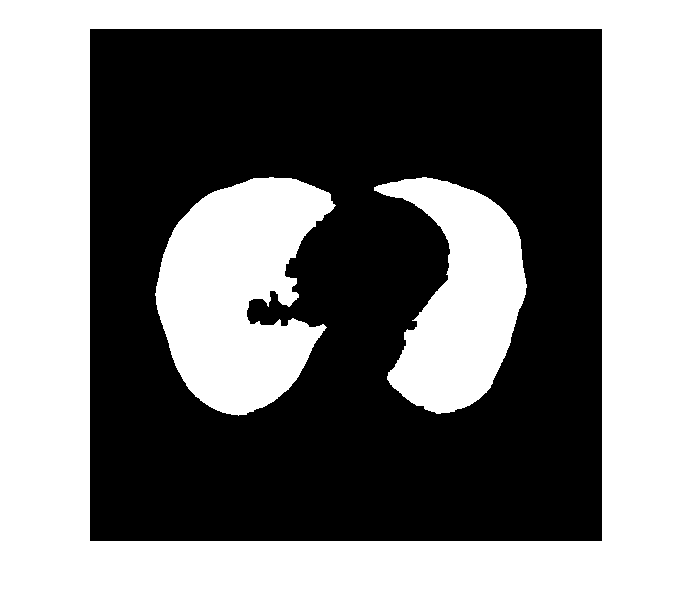

nhood=ones(5,5);
eroded=imerode(filled,nhood);
imshow(eroded)

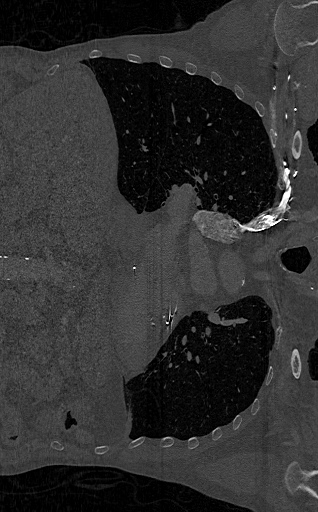

XZ=squeeze(V(256,:,:));
imshow(XZ,[],'Border','tight')

mask=false(size(V));
mask(:,:,160)